# Adquisición de Datos en la Estación de Validación

*Pellet Extruder*

**Descripción del código:**

Código para la toma de datos de sensores durante el proceso de extrusión en la estación de validación. Antes de comenzar con el muestreo sincronizado de datos, se comprueba que la máquina ha alcanzado el estado estacionario, tanto de temperatura como de flujo másico a lo largo del husillo, de forma que las condiciones sean óptimas durante la impresión y medida.

Se utiliza un Arduino para monitorizar las sondas NTC y un optoacoplador como tacómetro. Las células de carga se leen sin arduino, utilizando su API.

Klipper: resistencia inferior **319ºC**, superior **299ºC**.

POSICIÓN NTC's: (distancia medida desde base del barrel, sin noozle [TODAS TOCAN BARREL]

- **NTC 1 (ARRIBA)**: 68.6 mm

- **NTC 2**:60 mm

- **NTC 3**:47 mm

- **NTC 4 (ABAJO): **21.5 mm

Todos los parámetros y gráficas obtenidas se exportan en archivos xlsx para su posterior procesado. 

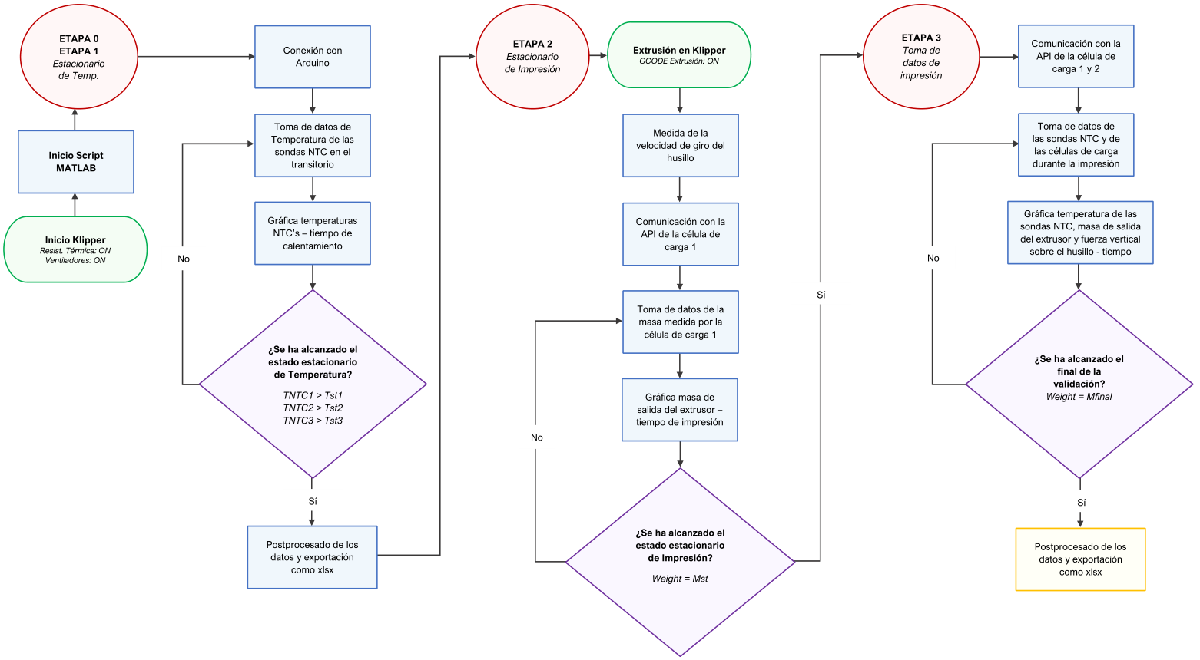

*(FlowChart: véase en el documento .docx adjunto)*

**Etapa 0:**** Conexión con Arduino y definición de variables**

waitfor(msgbox("OJO!!! CALIBRAR CÉLULA DE CARGA DE PRESIÓN ."));

clear all; % Clear workspace
a= arduino ('com4','ProMini328_5V');
LoadCell = addon(a,'basicHX711/basic_HX711',{'D5','D6'});
waitfor(msgbox("OJO!!! CALIBRAR BALANZA"));

prompt = {'Introduzca Nº DE VALORES PARA TOMAR LA MEDIDA:'};
dlgtitle = 'VALORES PARA TOMAR LA MEDIDA';
dims = [1 50];
n = inputdlg(prompt,dlgtitle,dims);
n1 = str2num(cell2mat(n));
prompt = {'Introduzca VALOR DEL PESO DE CALIBRACIÓN'};
dlgtitle = 'PESO DE CALIBRACIÓN';
dims = [1 50];
p = inputdlg(prompt,dlgtitle,dims);
p1 = str2num(cell2mat(p));

cal = calibration(n1,p1); % Empieza la calibración

cal.tare_weight = tare(cal,LoadCell); %taramos a cero la bascula
waitfor(msgbox("INTRODUCE LA 'PESA' DE CALIBRACIÓN ."));
cal.scale_factor = scale(cal,LoadCell); %con el peso obtenemos la escala

% Mostramos el peso de la calibración
weight = get_weight(cal,LoadCell);
name = 'Peso de calibración  ';   
peso = weight;
X = [name,'',num2str(peso),'g'];
disp(X)

Peso de calibración  49.9957g


waitfor(msgbox("CALIBRACIÓN FINALIZADA"));


%Configuración de las entradas
configurePin(a,"A0", "AnalogInput");
configurePin(a,"A1", "AnalogInput");
configurePin(a,"A2", "AnalogInput");
configurePin(a,"A3", "AnalogInput");






Indicar temperatura de las sondas NTC para las que se alcanza el estado estacionario:

T1st = 60;   % Temperatura sonda NTC1 (Pin A0) 60
T2st = 130;  % Temperatura sonda NTC2 (Pin A1) 130
T3st = 150;  % Temperatura sonda NTC3 (Pin A2) 170
T4st = 190;  % Temperatura sonda NTC4 (Pin A3) 330

Mst = 2;    % Umbral de masa de la LC1 para alcanzar el estacionario de impresión (g)
Mfinal = 4; % Masa recogida por la LC2 para finalizar la toma de datos durante la impresión (g)


Valores de las NTC:

R = 10000;% Resistencia fija del divisor de tensión  98000
R22= 82197.0; %821970  861970
beta = 3670; % Coeficiente del modelo BETA 3977
beta2= 4113;

waitfor(msgbox("INICIAR KLIPPER. CALENTAR Y ENCENDER VENTILADORES"));

**Etapa 1****: Comprobar que se ha alcanzado el estado estacionario de temperaturas para comenzar impresión**

Se leen los valores de temperatura de las sondas NTC dispuestas a lo largo del barrel. Se monitoriza su valor hasta alcanzar el estado estacionario dado por las variables de la etapa 0. En ese momento se salta a la siguiente etapa. Se realiza un simple postprocesado y se guardan los datos de calentamiento hasta llegar al estacionario como xlsx.

La relación T=f(R) de cada sonda se obtiene del datasheet del fabricante. En este caso, por falta de información, se utiliza la siguiente página web: [https://www.thinksrs.com/downloads/programs/therm%20calc/ntccalibrator/ntccalculator.html](https://www.thinksrs.com/downloads/programs/therm%20calc/ntccalibrator/ntccalculator.html) 

Se construye con el arduino y una resistencia de 100k (igual que la NTC a 25ºC) un divisor de tensión para poder realizar la medida.

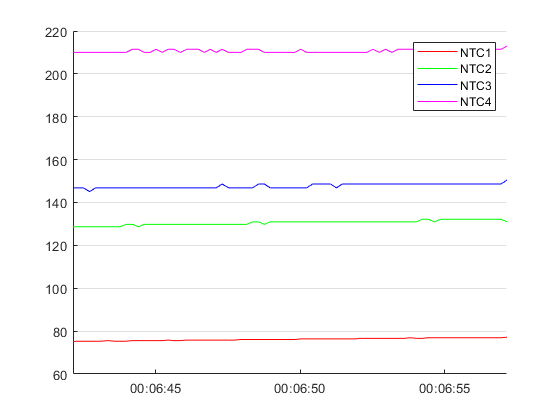

figure 

h1 = animatedline; % Crea ejes animados añadiendo el muestreo de datos en directo
h2 = animatedline;
h3 = animatedline;
h4 = animatedline;

ax = gca;
ax.YGrid = 'on'; 
% ax.YLim = [0 350]; % Límites del eje vertical

startTime = datetime('now'); % Current date and time

while 1
    % Lee el valor actual de tensión de cada sonda NTC
    v1 = readVoltage(a,'A0'); % Sonda NTC1 (Pin A0)
    R1 = R / ((5/v1)-1); % Divisor de tensión. Convierte la lectura de V a R.

    v2 = readVoltage(a,'A1'); % Sonda NTC2 (Pin A1)
    R2 = R / ((5/v2)-1); % Divisor de tensión. Convierte la lectura de V a R.

    v3 = readVoltage(a,'A2'); % Sonda NTC3 (Pin A2)
    R3 = R / ((5/v3)-1); % Divisor de tensión. Convierte la lectura de V a R.

    v4 = readVoltage(a,'A3'); % Sonda NTC4 (Pin A3)
    R4 = R/ ((5/v4)-1); % Divisor de tensión. Convierte la lectura de V a R.

    % Calcula la temperatura de cada sonda según el modelo Beta. Convierte
    % lectura de Tensión de cada NTC en Resistencia
    Temp1 = (1/(((log(R1/R))/beta)+(1/298.15)))-273.15; % Sonda NTC1 (Pin A0)
    Temp2 = (1/(((log(R2/R))/beta)+(1/298.15)))-273.15; % Sonda NTC2 (Pin A1)
    Temp3 = (1/(((log(R3/R))/beta)+(1/298.15)))-273.15; % Sonda NTC3 (Pin A2)
    Temp4 = (1/(((log(R4/R22))/beta2)+(1/298.15)))-273.15; % Sonda NTC4 (Pin A3)
    
    % Obtiene el tiempo exacto en el que se realiza el muestreo
    t =  datetime('now') - startTime;

    % Añade los datos de temperatura a la gráfica animada
    addpoints(h1,datenum(t),Temp1)
    addpoints(h2,datenum(t),Temp2)
    addpoints(h3,datenum(t),Temp3)
    addpoints(h4,datenum(t),Temp4)

    % Actualiza los ejes y el diseño del gráfico
    ax.XLim = datenum([t-seconds(15) t]);
    datetick('x','keeplimits')

    legend('NTC1', 'NTC2', 'NTC3','NTC4')
    h1.Color = 'r';
    h2.Color = 'g';
    h3.Color = 'b';
    h4.Color = 'm';

    drawnow

    % Comprobación. Sale del bucle si se ha alcanzado el estado estacionario de temperaturas 
    if (Temp1>T1st && Temp2>T2st && Temp3>T3st && Temp4>T4st)
        break
    end

end


% Mensaje info. se ha alcanzado el estacionario y se rompe el bucle
waitfor(msgbox("Se ha alcanzado el estacionario de temperatura. Comienza el postprocesado."));

- Plotea el muestreo de las sondas en pre-estacionario:

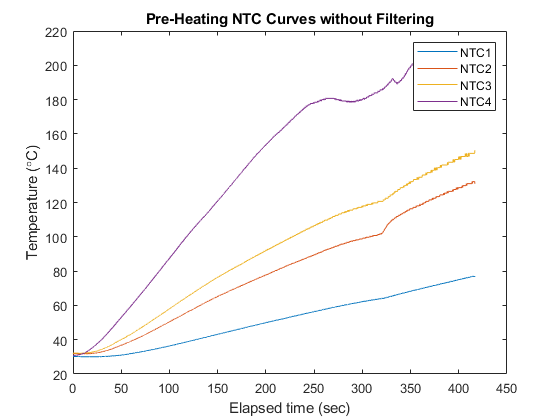

[timeLogs1,tempLogs1] = getpoints(h1); % Recupera los datos que definen la gráfica animada
[timeLogs2,tempLogs2] = getpoints(h2);
[timeLogs3,tempLogs3] = getpoints(h3);
[timeLogs4,tempLogs4] = getpoints(h4);

timeSecs1 = (timeLogs1-timeLogs1(1))*24*3600; % Conversión de unidades de tiempo
timeSecs2 = (timeLogs2-timeLogs2(1))*24*3600;
timeSecs3 = (timeLogs3-timeLogs3(1))*24*3600;
timeSecs4 = (timeLogs4-timeLogs4(1))*24*3600;

% Realiza el plot de las 3 sondas en una única gráfica
figure
plot(timeSecs1,tempLogs1,timeSecs2,tempLogs2,timeSecs3,tempLogs3, timeSecs4, tempLogs4)
title("Pre-Heating NTC Curves without Filtering")
xlabel('Elapsed time (sec)')
ylabel('Temperature (\circC)')
legend('NTC1', 'NTC2', 'NTC3', 'NTC4')

% Guarda una imagen de la gráfica en png
saveas(gcf,'PreNTC.png')

- Suaviza la gráfica utilizando el filtro de media móvil (Moving Average Filter):

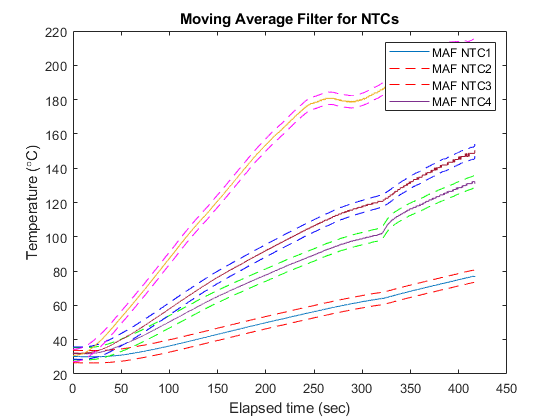

smoothedTemp1 = smooth(tempLogs1,25);
smoothedTemp2 = smooth(tempLogs2,25);
smoothedTemp3 = smooth(tempLogs3,25);
smoothedTemp4 = smooth(tempLogs4,25);

tempMax1 = smoothedTemp1 + 2*9/5;
tempMin1 = smoothedTemp1 - 2*9/5;

tempMax2 = smoothedTemp2 + 2*9/5;
tempMin2 = smoothedTemp2 - 2*9/5;

tempMax3 = smoothedTemp3 + 2*9/5;
tempMin3 = smoothedTemp3 - 2*9/5;

tempMax4 = smoothedTemp4 + 2*9/5;
tempMin4 = smoothedTemp4 - 2*9/5;


figure % Plot de las gráficas con la media movil máx y min

% Sonda NTC 1
plot(timeSecs1,tempLogs1, timeSecs1,tempMax1,'r--',timeSecs1,tempMin1,'r--')
hold on 

% Sonda NTC 2
plot(timeSecs2,tempLogs2, timeSecs2,tempMax2,'g--',timeSecs2,tempMin2,'g--')
hold on 

% Sonda NTC 3
plot(timeSecs3,tempLogs3, timeSecs3,tempMax3,'b--',timeSecs3,tempMin3,'b--')
hold on

% Sonda NTC 4
plot(timeSecs4,tempLogs4, timeSecs4,tempMax4,'m--',timeSecs4,tempMin4,'m--')
hold off

title("Moving Average Filter for NTCs")
xlabel('Elapsed time (sec)')
ylabel('Temperature (\circC)')
legend('MAF NTC1', 'MAF NTC2', 'MAF NTC3', 'MAF NTC4')

% Guarda una imagen de la gráfica en png
saveas(gcf,'PreNTC1.png')

- Plotea las señales de temperatura originales y las suavizadas, mostrando la incertidumbre:

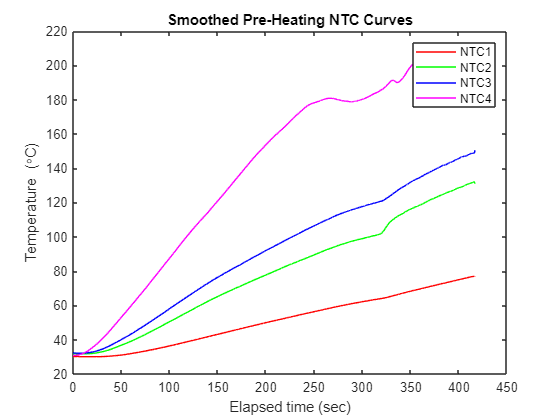

% Sonda NTC 1
plot(timeSecs1,smoothedTemp1,'r')
hold on

% Sonda NTC 2
plot(timeSecs2,smoothedTemp2,'g')
hold on

% Sonda NTC 3
plot(timeSecs3,smoothedTemp3,'b')
hold on

% Sonda NTC 4
plot(timeSecs4,smoothedTemp4,'m')
hold off

title("Smoothed Pre-Heating NTC Curves")
xlabel('Elapsed time (sec)')
ylabel('Temperature (\circC)')
legend('NTC1', 'NTC2', 'NTC3', 'NTC4')

% Guarda una imagen de la gráfica en png
saveas(gcf,'PreNTC2.png')

- Guarda los datos de calentamiento pre-estacionario medidos con las sondas en un archivo xlsx:

T1 = table(timeSecs1',tempLogs1','VariableNames',{'Time_sec','Temp_C'});
filename1 = 'Pre-Temperature_NTC1.xlsx';

T2 = table(timeSecs2',tempLogs2','VariableNames',{'Time_sec','Temp_C'});
filename2 = 'Pre-Temperature_NTC2.xlsx';

T3 = table(timeSecs3',tempLogs3','VariableNames',{'Time_sec','Temp_C'});
filename3 = 'Pre-Temperature_NTC3.xlsx';

T4 = table(timeSecs4',tempLogs4','VariableNames',{'Time_sec','Temp_C'});
filename4 = 'Pre-Temperature_NTC4.xlsx';

% Escribe los datos en los archivos:
writetable(T1,filename1)
writetable(T2,filename2)
writetable(T3,filename3)
writetable(T4,filename4)

% Mensaje info. postprocesado realizado y archivos guardados
waitfor(msgbox("Postprocesado realizado y archivos guardados. Comenzar a extruir."));

**Etapa 2****: Comunicación con la API de las Células de Carga y Comprobación Estacionario Flujo Másico. Medida rpm husillo.**

A continuación, se comienza a extruir plástico. Se comprobará que el extrusor a impreso la cantidad de plástico suficiente como para considerar el etacionario de impresión y poder comenzar con la toma de datos durante la impresión. Para ello se comprobarán las medidas obtenidas en la célula de carga de 1kg (LC1). Cuando se alcance un valor umbral fijado por el usuario, se considerará alcanzado el estacionario de impresión y se comenzará con la Etapa 3 de toma de datos durante la impresión.

- Medida RPM del husillo:

waitfor(msgbox("Ponga en marcha el extrusor y empiece a imprimir"));

%% Record and plot 10 seconds of temperature data
tic % Inicia medida de tiempo
kk=0;
while toc < 10

    taco=readDigitalPin(a,'D2'); % Lecutra pin digital optoacoplador

    if taco == 1 % Suma 1 cuando da una revolución y se bloquea el IR del optoacoplador
    kk = kk + 1;
    end

end
toc % Obtiene tiempo final

Elapsed time is 10.012552 seconds.



RPM = 60*kk/(toc*8) % Calcula las RPM

RPM = 77.8573


% Guarda el valor en un archivo xlsx
Trpm = table(RPM,'VariableNames',{'RPM screw'});
filenameRPM = 'RPM.xlsx';
writetable(Trpm,filenameRPM)

waitfor(msgbox(sprintf('El husillo gira a %2.3g rpm',RPM),'RPM'));

- Comunicación con la API de la LC1:

% import com.tinkerforge.IPConnection;
% import com.tinkerforge.BrickletLoadCellV2;
% 
% HOST = 'localhost';
% PORT = 4223;
% UID1 = 'ZUB'; % Fijar el valor de la UID de la Load Cell Bricklet 2.0. Ver con Brick Viewer Software
% 
% ipcon = IPConnection(); % Crea la IP connection
% lc = handle(BrickletLoadCellV2(UID1, ipcon), 'CallbackProperties'); % Crea objeto del dispositivo
% 
% ipcon.connect(HOST, PORT); % Conecta con el software intermediario Brick Daemon. No utiliza el dispositivo hasta que la ipcon esté establecida

- Comprobación de la masa de plástico impresa para llegar al estacionario de impresión:

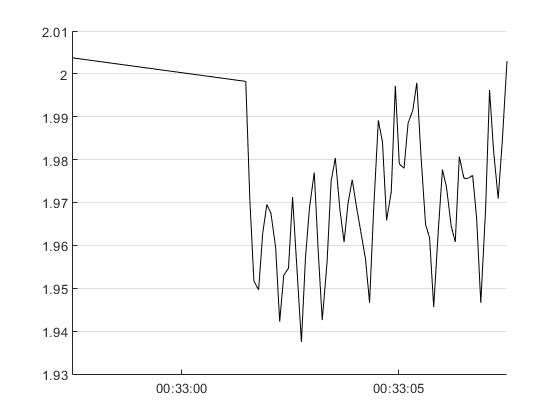

% Crea un plot animado para visualizar los datos
figure

h = animatedline;

ax = gca;
ax.YGrid = 'on';
% ax.YLim = [0 350]; % Límites del eje vertical

startTime = datetime('now'); % Current date and time

while 1
    % Obtiene el peso actual
%     weight = lc.getWeight();
    weight = get_weight(cal,LoadCell);

    % Obtiene el tiempo de muestreo
    t =  datetime('now') - startTime;

    % Añade los valores obtenidos al gráfico animado
    addpoints(h,datenum(t),weight)

    % Actualiza los ejes
    ax.XLim = datenum([t-seconds(10) t]);
    datetick('x','keeplimits')
    drawnow

    % Comprobación. Si se alcanza el estacionario de impresión sale del bucle
    if weight >= Mst
        pause (8)
        weight = get_weight(cal,LoadCell);
        if weight >= Mst
            break
        end
    end

end


% ipcon.disconnect(); % Termina la conexión con la API

% Mensaje info. se ha alcanzado el estacionario de impresión

waitfor(msgbox("Estacionario de impresión alcanzado. Comienza la toma de datos de impresión."));

**Etapa 3****: Toma de datos del proceso de impresión para la validación de las simulaciones**

Una vez alcanzado el estado estacionario, se sincroniza la toma de datos de todos los sensores para la validación de las simulaciones. Posteriormente, estos datos se exportarán en formato xlsx. 

Sensores:

- 4 Sondas NTC.

- 1 Célula de Carga de 1kg (LC1) para medida de flujo másico.

- 1 Célula de Carga de 20 kg (LC2) para medida de fuerzas sobre el husillo.

- Comunicación con la API de la LC1 y la LC2:

import com.tinkerforge.IPConnection;
import com.tinkerforge.BrickletLoadCellV2;

HOST = 'localhost';
PORT = 4223;
%UID1 = 'ZUB'; % Fijar el valor de la UID1 de la Load Cell 1kg Bricklet 2.0. Ver con Brick Viewer Software
UID2 = 'ZUF'; % Fijar el valor de la UID2 de la Load Cell 20kg Bricklet 2.0. Ver con Brick Viewer Software

ipcon = IPConnection(); % Crea la IP connection
%lc1 = handle(BrickletLoadCellV2(UID1, ipcon), 'CallbackProperties'); % Crea objeto del dispositivo 1
lc2 = handle(BrickletLoadCellV2(UID2, ipcon), 'CallbackProperties'); % Crea objeto del dispositivo 2

ipcon.connect(HOST, PORT); % Conecta con el software intermediario Brick Daemon. No utiliza el dispositivo hasta que la ipcon esté establecida
    

- Toma de datos de la LC1, LC2 y NTC's:

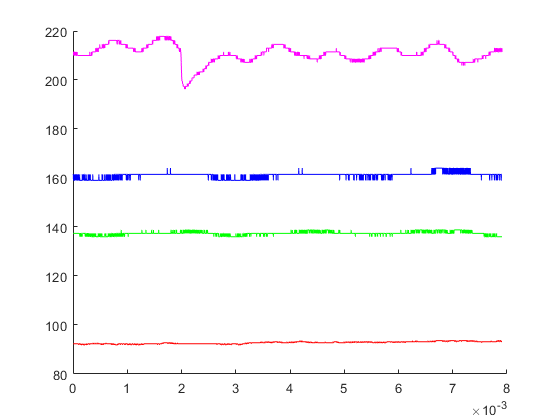

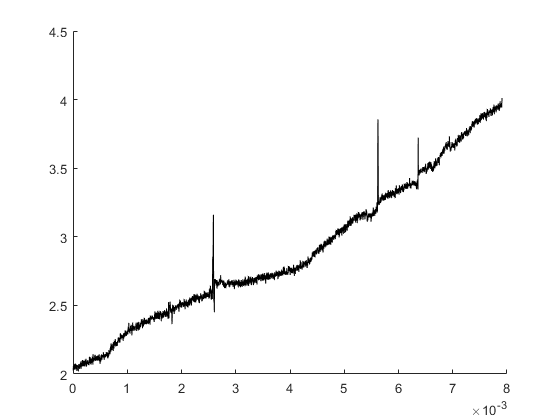

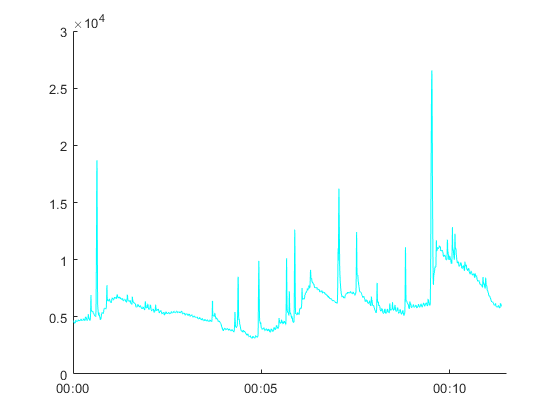

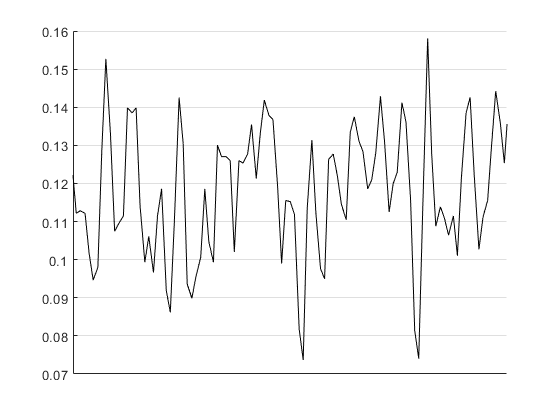

% Crea un plot animado para visualizar los datos
figure
h1 = animatedline; % NTC1
h2 = animatedline; % NTC2
h3 = animatedline; % NTC3
h4 = animatedline; % NTC4

figure
h5 = animatedline; % LC1

figure
h6 = animatedline; % LC2

ax.YGrid = 'on';
% ax.YLim = [0 1000]; % Límites del eje vertical

startTime = datetime('now'); % Current date and time

while 1
    % Lee el valor actual de tensión de cada sonda NTC
    v1 = readVoltage(a,'A0'); % Sonda NTC1 (Pin A0)
    R1 = R / ((5/v1)-1); % Divisor de tensión. Convierte la lectura de V a R.

    v2 = readVoltage(a,'A1'); % Sonda NTC2 (Pin A1)
    R2 = R / ((5/v2)-1); % Divisor de tensión. Convierte la lectura de V a R.

    v3 = readVoltage(a,'A2'); % Sonda NTC3 (Pin A2)
    R3 = R / ((5/v3)-1); % Divisor de tensión. Convierte la lectura de V a R.

    v4 = readVoltage(a,'A3'); % Sonda NTC4 (Pin A3)
    R4 = R / ((5/v4)-1); % Divisor de tensión. Convierte la lectura de V a R.

    % Obtiene el peso actual de cada Célula de Carga
    weight1 = get_weight(cal,LoadCell);
    weight2 = lc2.getWeight();

    % Calcula la temperatura de cada sonda según el modelo Beta. Convierte
    % lectura de Tensión de cada NTC en Resistencia
    Temp1 = (1/(((log(R1/R))/beta)+(1/298.15)))-273.15; % Sonda NTC1 (Pin A0)
    Temp2 = (1/(((log(R2/R))/beta)+(1/298.15)))-273.15; % Sonda NTC2 (Pin A1)
    Temp3 = (1/(((log(R3/R))/beta)+(1/298.15)))-273.15; % Sonda NTC3 (Pin A2)
    Temp4 = (1/(((log(R4/R22))/beta2)+(1/298.15)))-273.15; % Sonda NTC4 (Pin A3)

    % Obtiene el tiempo exacto en el que se realiza el muestreo
    t =  datetime('now') - startTime;

    % Añade los datos de temperatura a la gráfica animada
    addpoints(h1,datenum(t),Temp1)
    addpoints(h2,datenum(t),Temp2)
    addpoints(h3,datenum(t),Temp3)
    addpoints(h4,datenum(t),Temp4)
    addpoints(h5,datenum(t),weight1)
    addpoints(h6,datenum(t),weight2)

    % Actualiza los ejes y su diseño
    ax.XLim = datenum([t-seconds(10) t]);
    datetick('x','keeplimits')
    
    h1.Color = 'r';
    h2.Color = 'g';
    h3.Color = 'b';
    h4.Color = 'm';
    h5.Color = 'k';
    h6.Color = 'c';

    drawnow

    % Comprobación. Si se alcanza el estacionario de impresión sale del bucle
    if weight1 >=  Mfinal;
        pause (8)
        weight1 = get_weight(cal,LoadCell); %get_weight(cal,LoadCell) lc1.getWeight()
        if weight1 >= Mfinal
            break
        end
        
    end

end


% ipcon.disconnect(); % Termina la conexión con la API

% Mensaje info. se ha alcanzado el estacionario de impresión. Guarda el
% valor de la masa pesada en báscula para compararlo con el de la célula de
% carga
prompt = {'Introduzca masa pesada en báscula:'};
dlgtitle = 'Masa pesada en báscula';
dims = [1 35];
masaBasc = inputdlg(prompt,dlgtitle,dims)

masaBasc = 1×1 cell array
    {'4.1'}


% Guarda el valor en un archivo xlsx
Mbasc = table(masaBasc,'VariableNames',{'Masa Báscula vs 4g'});
filenameMB = 'masaBascula.xlsx';
writetable(Trpm,filenameMB)

%bascula1= 3.750 g ;

waitfor(msgbox("Ha finalizado la toma de datos. A continuación, se realizará el postprocesado."));        

- Plotea el muestreo de datos durante la impresión:

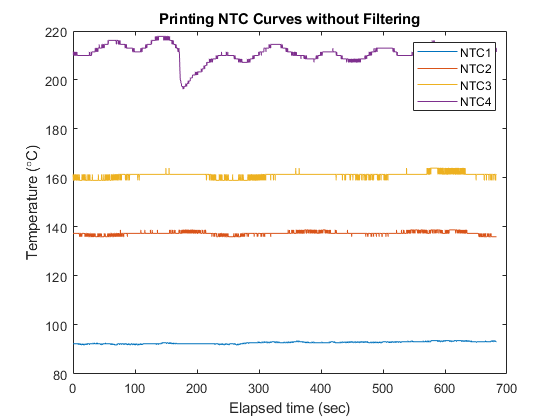

[timeLogs1,tempLogs1] = getpoints(h1); % Recupera los datos que definen la gráfica animada
[timeLogs2,tempLogs2] = getpoints(h2);
[timeLogs3,tempLogs3] = getpoints(h3);
[timeLogs4,tempLogs4] = getpoints(h4);
[timeLogs5,tempLogs5] = getpoints(h5);
[timeLogs6,tempLogs6] = getpoints(h6);

timeSecs1 = (timeLogs1-timeLogs1(1))*24*3600; % Conversión de unidades de tiempo
timeSecs2 = (timeLogs2-timeLogs2(1))*24*3600;
timeSecs3 = (timeLogs3-timeLogs3(1))*24*3600;
timeSecs4 = (timeLogs4-timeLogs4(1))*24*3600;
timeSecs5 = (timeLogs5-timeLogs5(1))*24*3600;
timeSecs6 = (timeLogs6-timeLogs6(1))*24*3600;

% Realiza el plot de las 4 sondas en una única gráfica:
figure
plot(timeSecs1,tempLogs1,timeSecs2,tempLogs2,timeSecs3,tempLogs3,timeSecs4,tempLogs4)
title("Printing NTC Curves without Filtering")
xlabel('Elapsed time (sec)')
ylabel('Temperature (\circC)')
legend('NTC1', 'NTC2', 'NTC3', 'NTC4')
% Guarda una imagen de la gráfica en png
saveas(gcf,'NTCprinting.png')

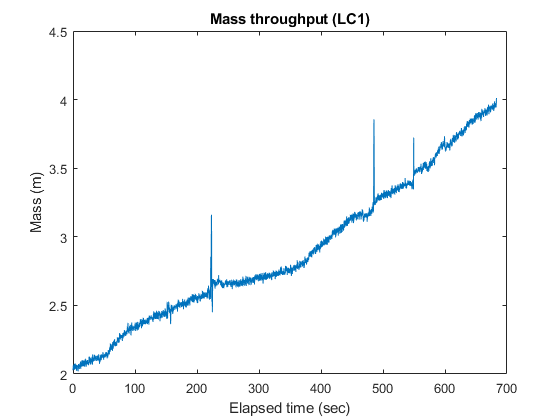


% Realiza el plot de la LC1:
figure
plot(timeSecs5,tempLogs5)
title("Mass throughput (LC1)")
xlabel('Elapsed time (sec)')
ylabel('Mass (m)')
% Guarda una imagen de la gráfica en png
saveas(gcf,'MassThroughputPrinting.png')

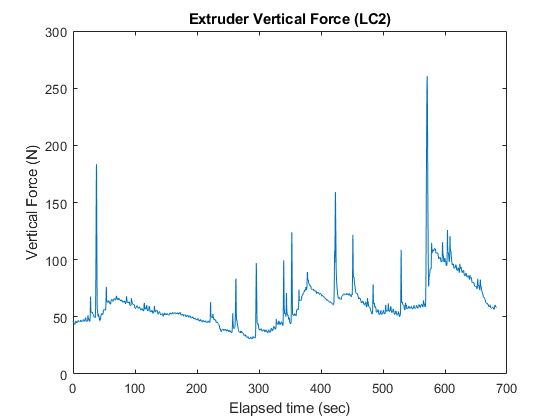


% Realiza el plot de la LC2:
Force = tempLogs6*9.81/1000; % Conversión a Newtons. Comprobar unidades.

figure
plot(timeSecs6,Force)
title("Extruder Vertical Force (LC2)")
xlabel('Elapsed time (sec)')
ylabel('Vertical Force (N)')
% Guarda una imagen de la gráfica en png
saveas(gcf,'ExtruderForcePrinting.png')

- Suaviza la gráfica utilizando el filtro de media móvil (Moving Average Filter):

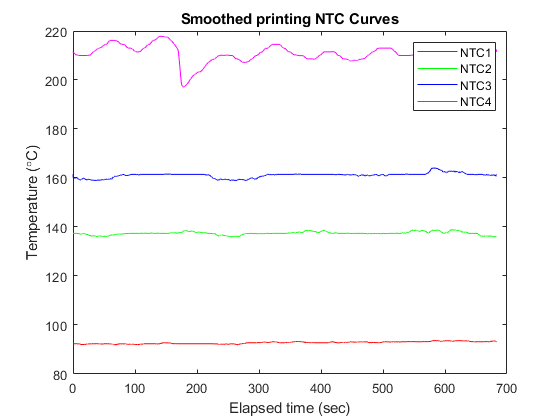

smoothedTemp1 = smooth(tempLogs1,25);
smoothedTemp2 = smooth(tempLogs2,25);
smoothedTemp3 = smooth(tempLogs3,25);
smoothedTemp4 = smooth(tempLogs4,25);
smoothedMass1 = smooth(tempLogs5,25);
smoothedMass2 = smooth(Force,25);

tempMax1 = smoothedTemp1 + 2*9/5;
tempMin1 = smoothedTemp1 - 2*9/5;

tempMax2 = smoothedTemp2 + 2*9/5;
tempMin2 = smoothedTemp2 - 2*9/5;

tempMax3 = smoothedTemp3 + 2*9/5;
tempMin3 = smoothedTemp3 - 2*9/5;

tempMax4 = smoothedTemp4 + 2*9/5;
tempMin4 = smoothedTemp4 - 2*9/5;

massMax1 = smoothedMass1 + 2*9/5;
massMin1 = smoothedMass1 - 2*9/5;

massMax2 = smoothedMass2 + 2*9/5;
massMin2 = smoothedMass2 - 2*9/5;

figure % Plot de las gráficas suavizadas

% Sonda NTC 1
plot(timeSecs1,smoothedTemp1,'r')
hold on

% Sonda NTC 2
plot(timeSecs2,smoothedTemp2,'g')
hold on

% Sonda NTC 3
plot(timeSecs3,smoothedTemp3,'b')
hold on

% Sonda NTC 4
plot(timeSecs4,smoothedTemp4,'m')
hold off

title("Smoothed printing NTC Curves")
xlabel('Elapsed time (sec)')
ylabel('Temperature (\circC)')
legend('NTC1', 'NTC2', 'NTC3', 'NTC4')

% Guarda una imagen de la gráfica en png
saveas(gcf,'NTC.png')

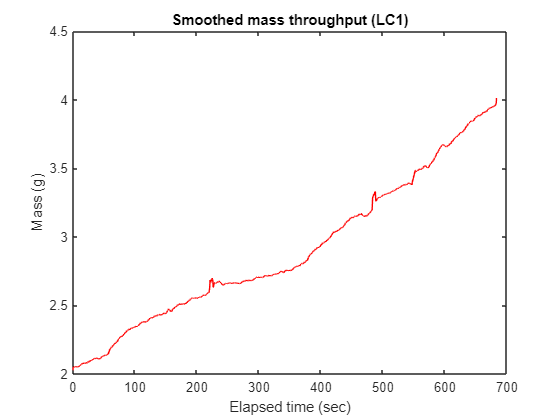


% Célula de carga LC1
plot(timeSecs5,smoothedMass1,'r')
title("Smoothed mass throughput (LC1)")
xlabel('Elapsed time (sec)')
ylabel('Mass (g)')

% Guarda una imagen de la gráfica en png
saveas(gcf,'LC1.png')

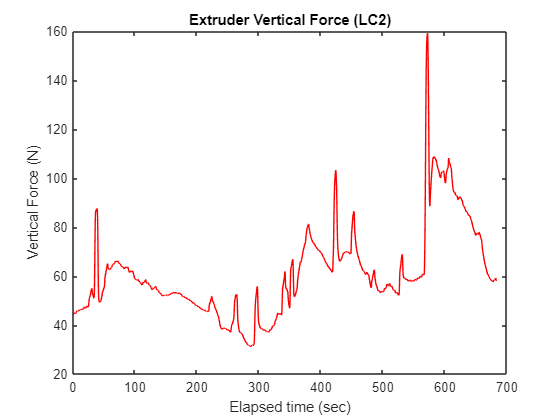


% Célula de carga LC2
plot(timeSecs6,smoothedMass2,'r')
title("Extruder Vertical Force (LC2)")
xlabel('Elapsed time (sec)')
ylabel('Vertical Force (N)')

% Guarda una imagen de la gráfica en png
saveas(gcf,'LC2.png')

- Guarda los datos de impresión en un archivo xlsx:

T1 = table(timeSecs1',tempLogs1','VariableNames',{'Time_sec','Temp_C'});
filename1 = 'PrintTemperature_NTC1.xlsx';

T2 = table(timeSecs2',tempLogs2','VariableNames',{'Time_sec','Temp_C'});
filename2 = 'PrintTemperature_NTC2.xlsx';

T3 = table(timeSecs3',tempLogs3','VariableNames',{'Time_sec','Temp_C'});
filename3 = 'PrintTemperature_NTC3.xlsx';

T4 = table(timeSecs4',tempLogs4','VariableNames',{'Time_sec','Temp_C'});
filename4 = 'PrintTemperature_NTC4.xlsx';

T5 = table(timeSecs5',tempLogs5','VariableNames',{'Time_sec','g'});
filename5 = 'Mass_Trhoughput.xlsx';

T6 = table(timeSecs6',Force','VariableNames',{'Time_sec','N'});
filename6 = 'Vertical_Force_Screw.xlsx';

% Escribe los datos en los archivos:
writetable(T1,filename1)
writetable(T2,filename2)
writetable(T3,filename3)
writetable(T4,filename4)
writetable(T5,filename5)
writetable(T6,filename6)

% Mensaje info. toma de datos finalizada
waitfor(msgbox("Experimento de validación finalizado"));